# BME3053C Final Project

## Team: Eye Believe

### Project: Eye Spy a Disease

Authors: Vanessa Cruz, Parker Kotlarz, Cristina Williams

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: kotlarz.parker@ufl.edu

April 11, 2021

Code Adapted and Modified from MATLAB AI Signals Workshop (04/05/2021)

% After the Line Indicates Modification/Added from the Original Code

## Setting Up the Convolution Neural Network (CNN)

Step 1: Establish the pretrained network Alexnet in MATLAB

network = alexnet; %
layers = network.Layers; %

Step 2: Modify layers 23-25 to change Alexnet from general image classifcation to specifically recognizing eye diseases

layers(23) = fullyConnectedLayer(4); %
layers(24) = softmaxLayer(); 
layers(25) = classificationLayer("Classes", ...
    {'Bulging' 'Cataracts' 'Healthy' 'Uveitis'}); %

## Creating Training and Testing Sets with the Data

Step 3: Load the image data with their correct label. Image must be converted to 227x227 for Alexnet.

readFcn = @(imagefilename)imresize(imread(imagefilename), [227 227]);
filepath = "Eye_Images_Finalized"; %
allImages = imageDatastore(filepath, 'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames', 'ReadFcn', readFcn);

Step 4: Split the images into training and testing sets (optimal 0.7 or 0.8)

split = 0.8%

split = 0.8000

[trainingImages, testImages] = splitEachLabel(allImages, split, 'randomize'); %

## Training the CNN on the Data

Step 5: Train the network on the training set (optimal epochs: 12-15, optimal batch: 4-6)

epoch = 8%

epoch = 8

batch = 4%

batch = 4

options = trainingOptions('sgdm', 'InitialLearnRate', 0.0001, ...
    'MaxEpochs', epoch, 'MiniBatchSize', batch ,'Plots', ...
    'training-progress', 'ExecutionEnvironment',"auto"); %

Section break included to allow for change in epoch/batch without automatically retraining the network

Training on single CPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:02 |        0.00% |       2.7748 |      1.0000e-04 |


|       4 |          50 |       00:00:35 |      100.00% |       0.0023 |      1.0000e-04 |


|       7 |         100 |       00:01:04 |      100.00% |       0.0042 |      1.0000e-04 |


|       8 |         120 |       00:01:15 |      100.00% |       0.0111 |      1.0000e-04 |
|========================================================================================|


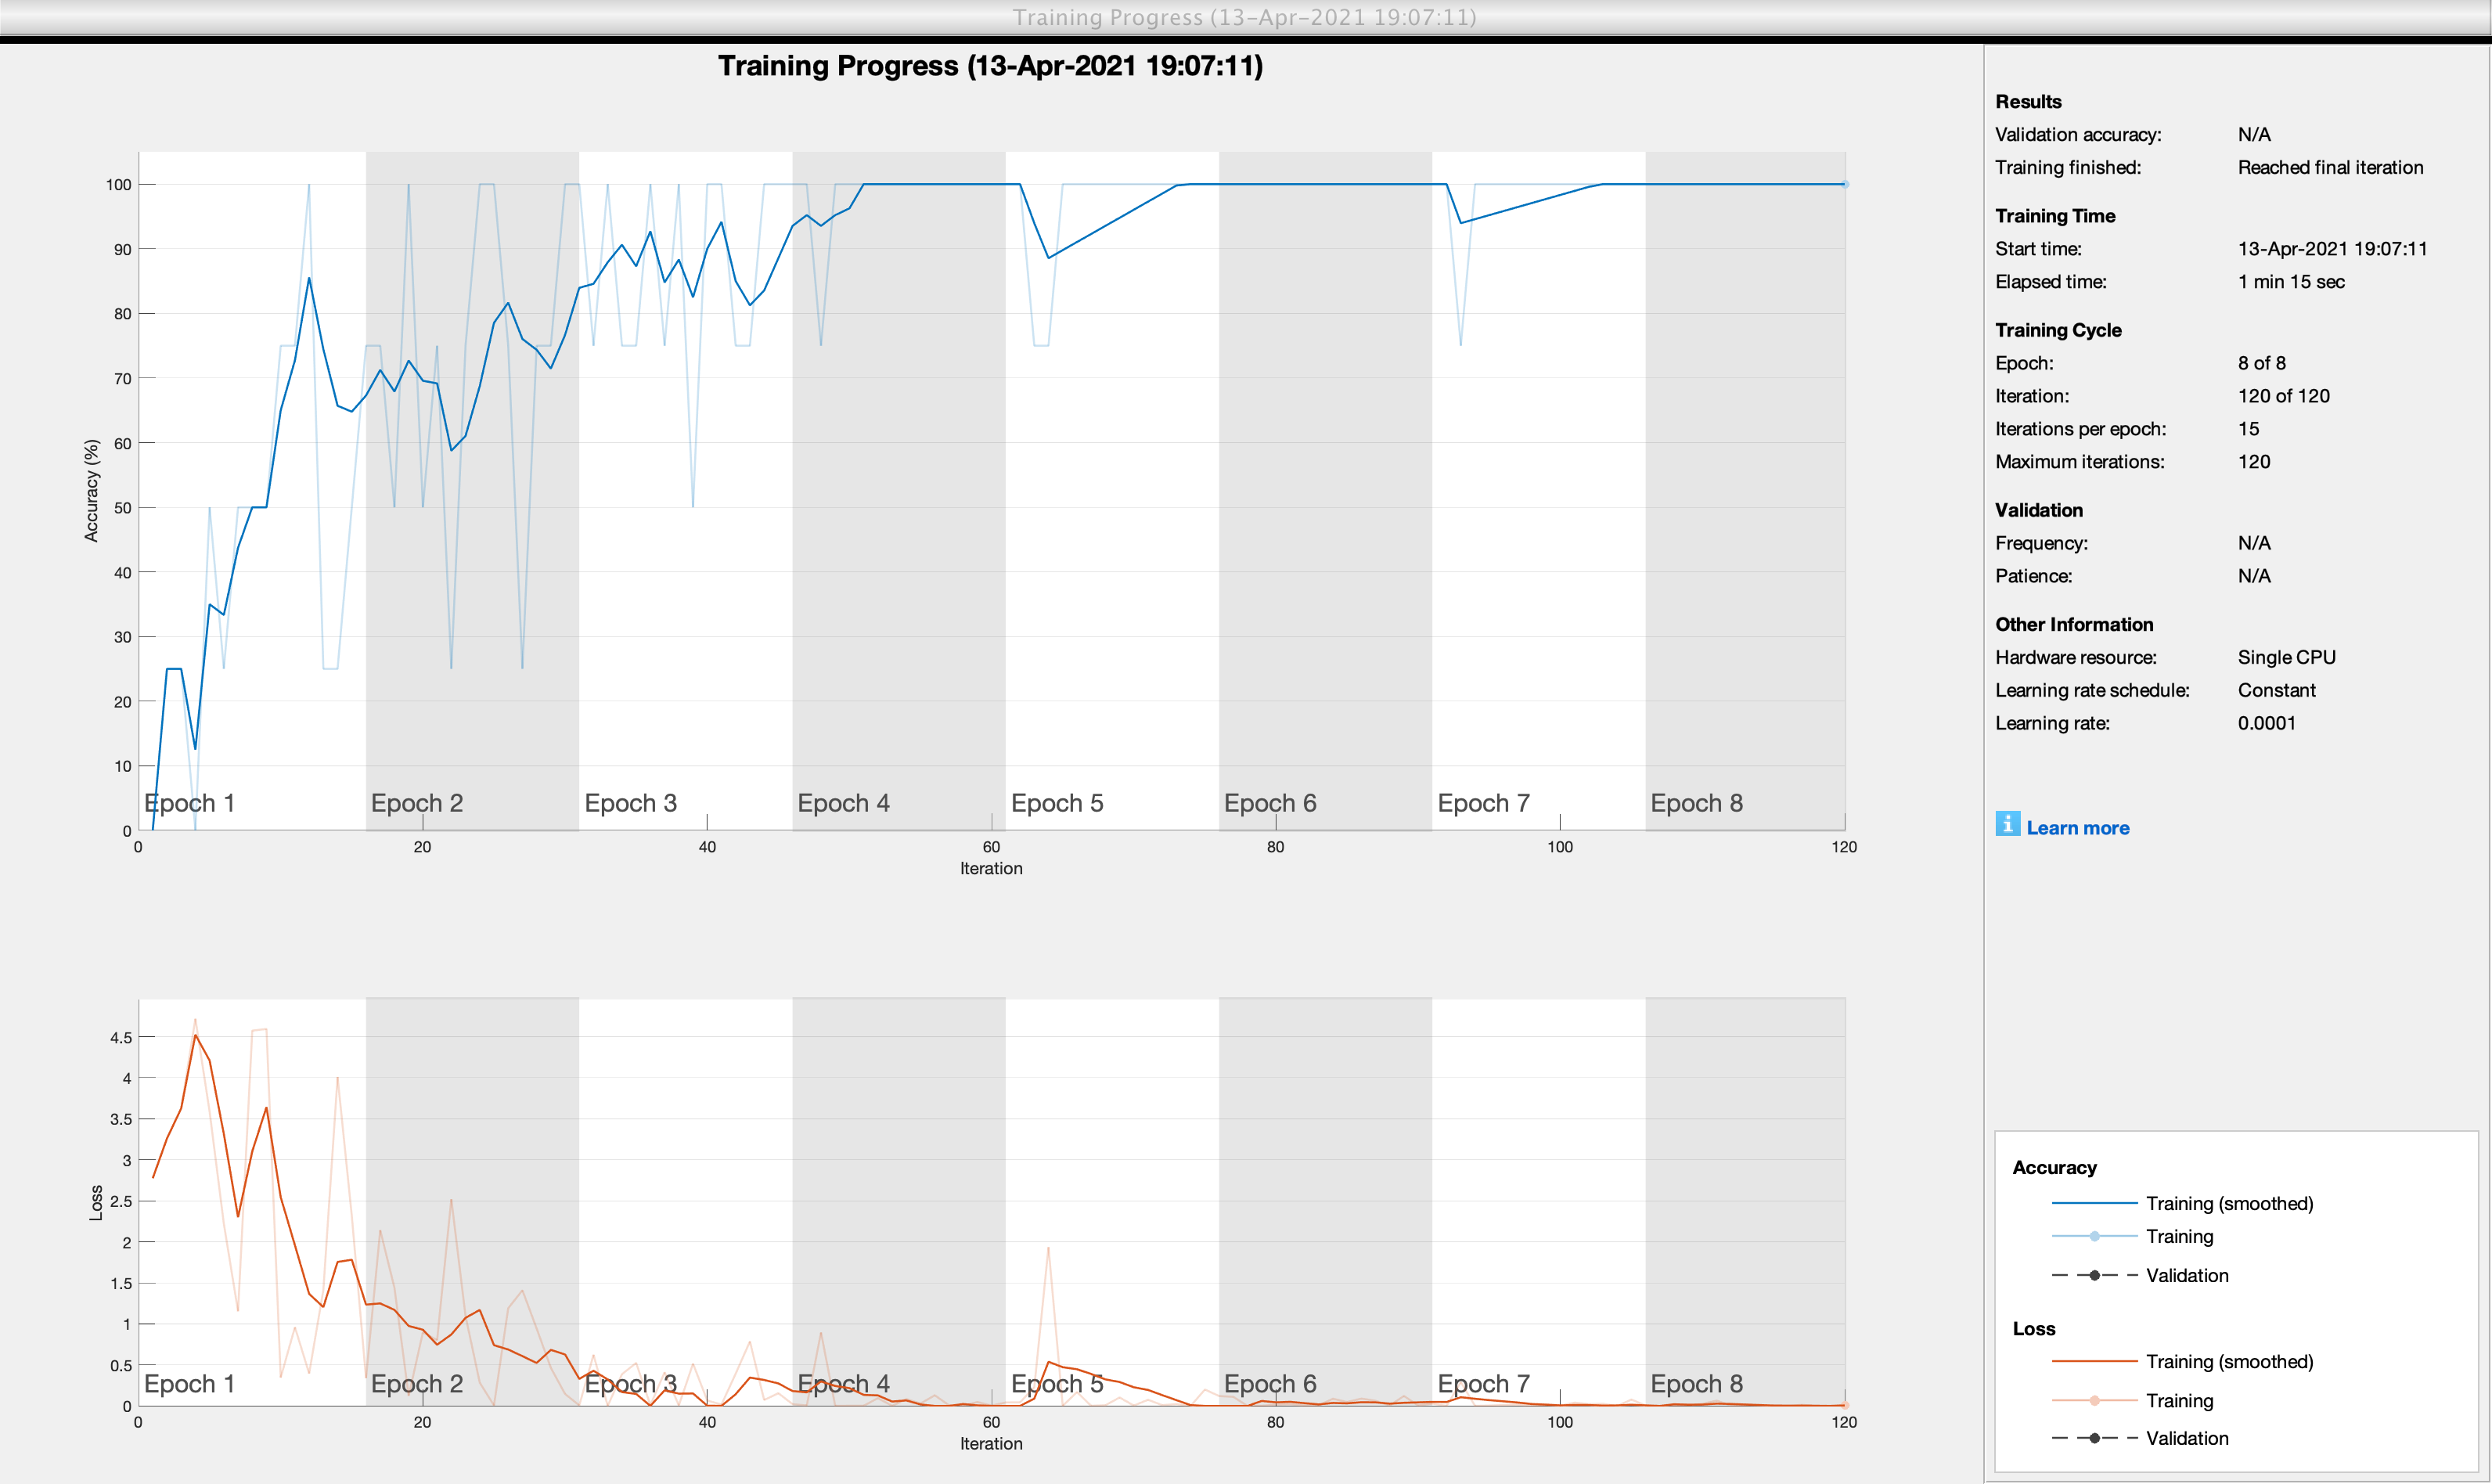

EyeNet = trainNetwork(trainingImages, layers, options); %

## Testing the CNN on Eye Disease Classification

Step 6: Test the newly trained network on the testing set

predictedLabels = classify(EyeNet, testImages);

Step 7: Analyze accuracy of the network using a confusion matrix

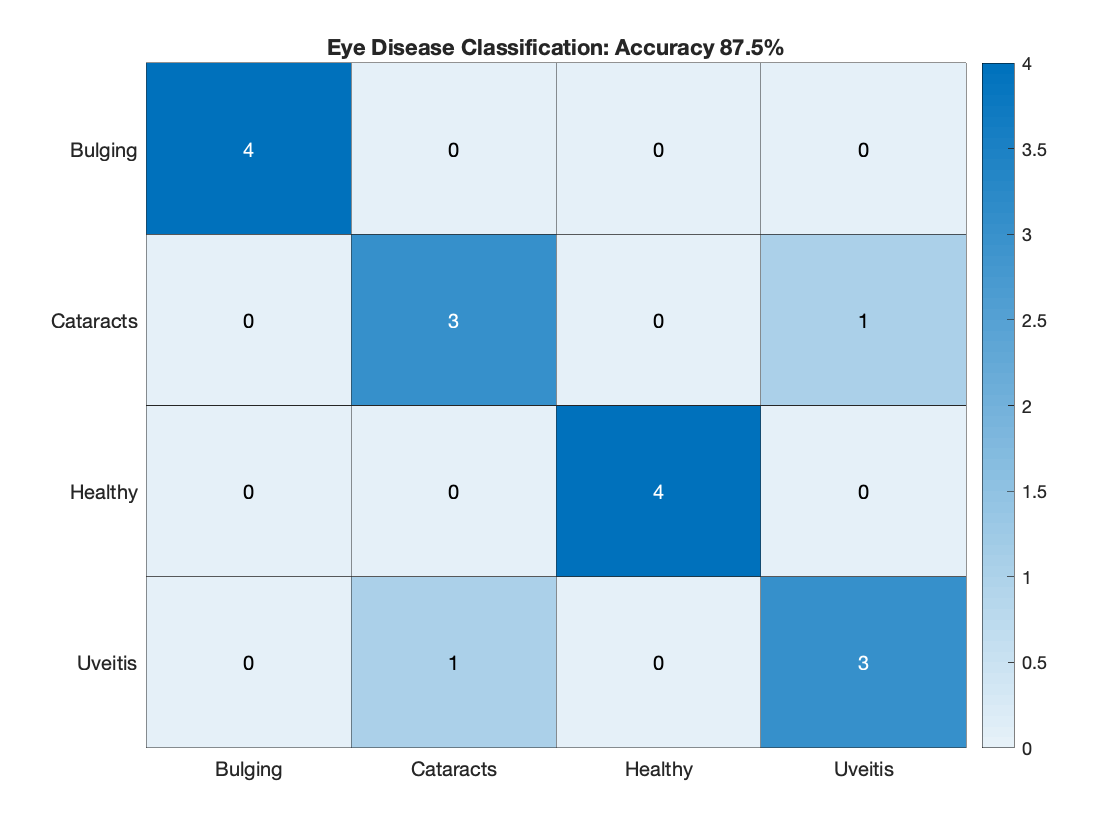

accuracy = sum(predictedLabels == testImages.Labels) / numel(predictedLabels);
[confmat, order] = confusionmat(testImages.Labels, predictedLabels);
figure
heatmap(order, order, confmat);
title("Eye Disease Classification: Accuracy " + accuracy*100 + "%") %

## Individual Image Analysis

Example of using the trained network to analyze an individual image

Step 1: Load the image

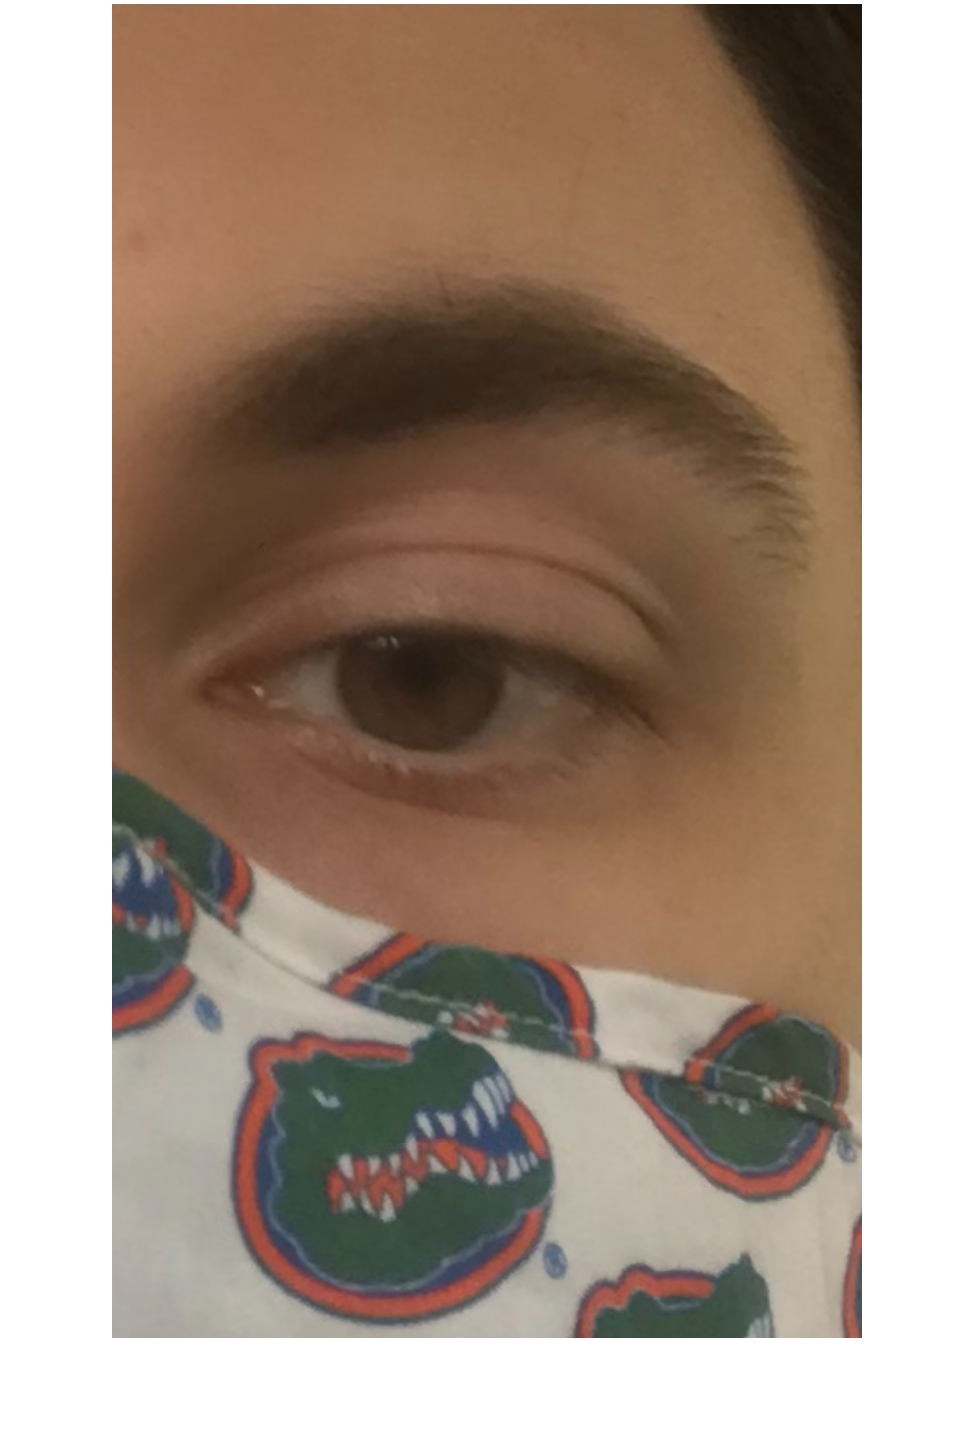

eye = imread('Pkmask.jpeg'); %
imshow(eye); %

Step 2: Resize the image to 227 x 227

eyeR = imresize(eye, [227 227]); %

Step 3: Use the trained network to classify the image

classify(EyeNet,eyeR) %

ans = categorical
     Healthy 
